**PATHS**

addpath('/Users/Micha/Workspaces/matlab/processfits/src')
addpath('/Users/Micha/data/20180605/src');

fitspath = '/Users/Micha/data/20180605/data';
homepath = '/Users/Micha/data/20180605';
matpath = '/Users/Micha/data/20180605/mat';


BIAS, DARK and FLAT

cd(homepath);
load(strcat(homepath,'/','mat/','flat_rgb.mat'));
load(strcat(homepath,'/','mat/','dark_rgb.mat'));
load(strcat(homepath,'/','mat/','bias_rgb.mat'));

normflat(:,:,1) = flat(:,:,1) ./ max(max(flat(:,:,1)));
normflat(:,:,2) = flat(:,:,2) ./ max(max(flat(:,:,2)));
normflat(:,:,3) = flat(:,:,3) ./ max(max(flat(:,:,3)));

sz = size(flat)

sz =         3284        4944           3


szsz = size(sz)

szsz =      1     3


Channel

chnl = 2

chnl = 2

Intensity

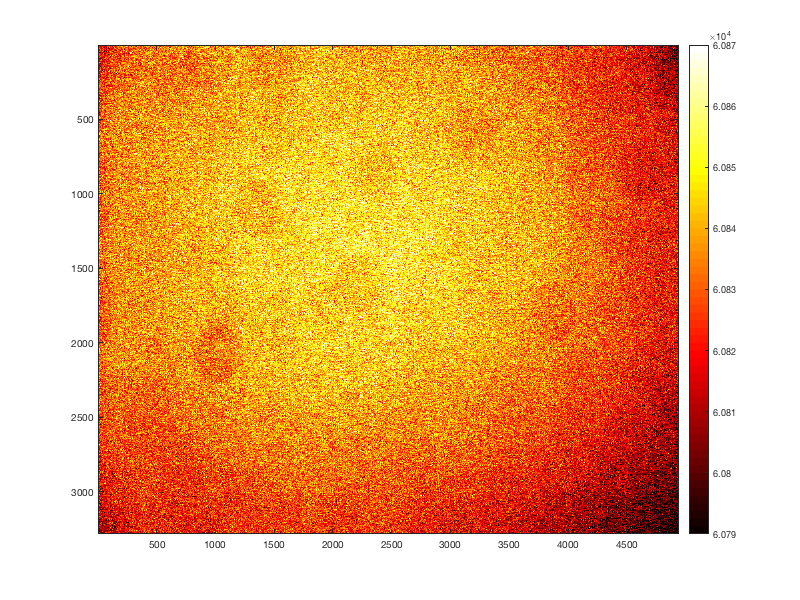

figure('Position',[1 1 800 600])
imagesc(flat(:,:,chnl),[60790 60870])
colormap('hot')
colorbar()

Gradient

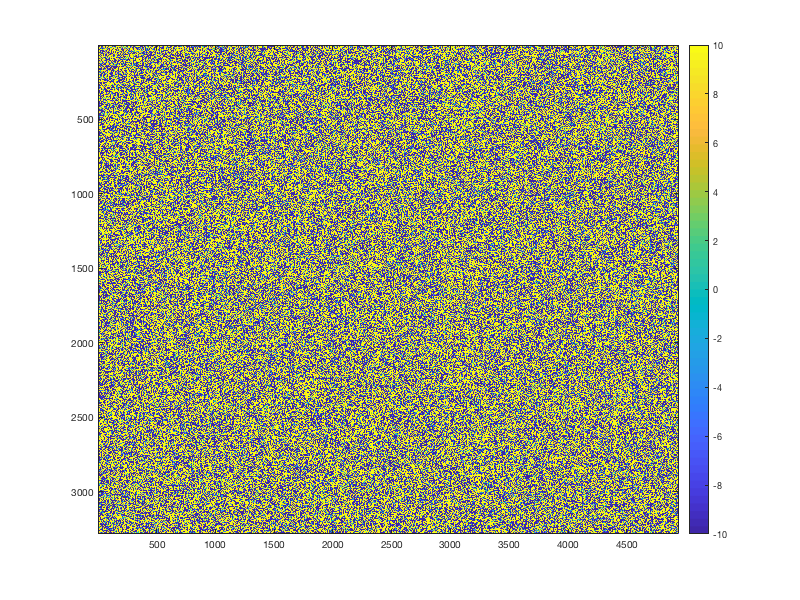

figure('Position',[1 1 800 600])
delta = 10;
df = gradient(flat(:,:,chnl));
imagesc(df,[-10 10])
colorbar()

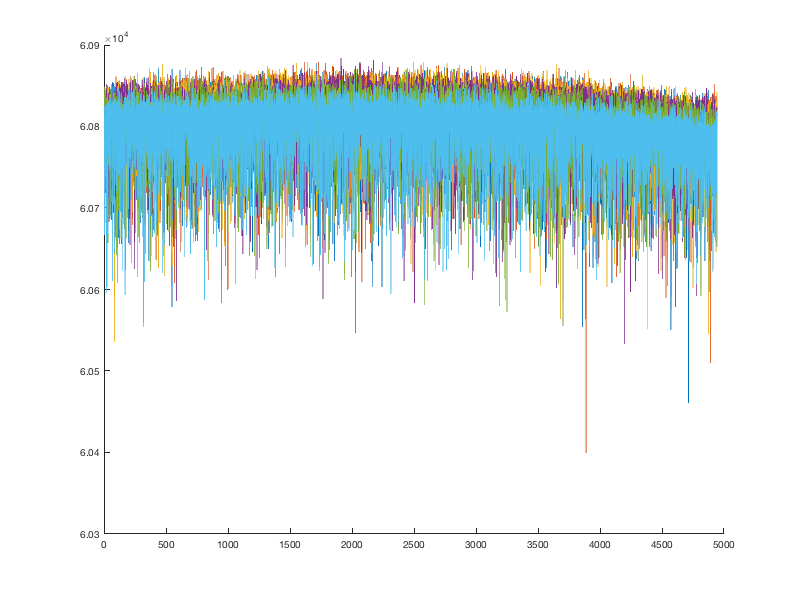

figure('Position',[1 1 800 600])
hold on
for row = 500:500:3000
    plot(flat(row,:,chnl))
end
hold off

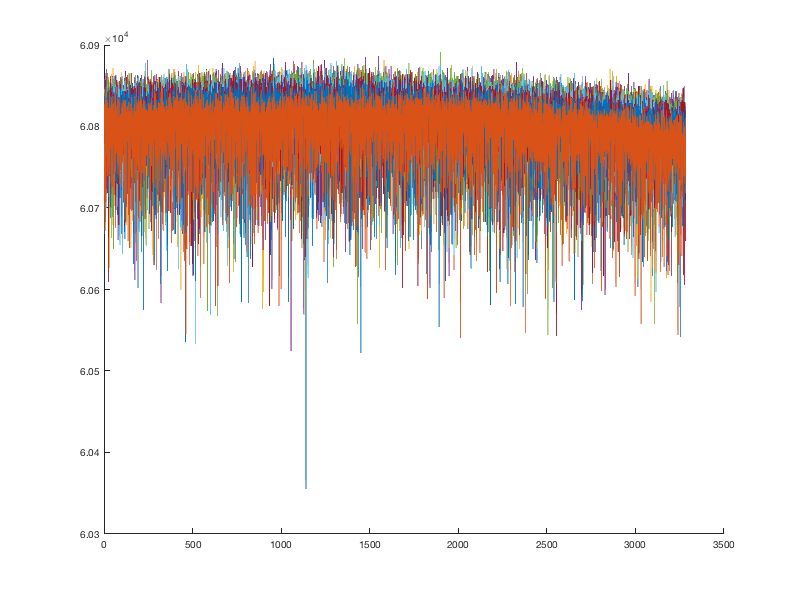

figure('Position',[1 1 800 600])
hold on
for col = 500:500:4500
    plot(flat(:,col,chnl))
end
hold off

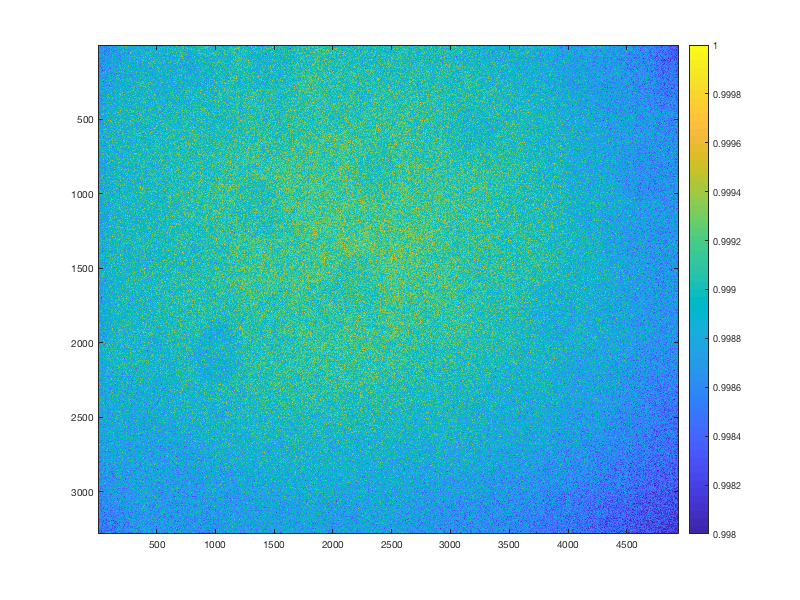



figure('Position',[1 1 800 600])
imagesc(normflat(:,:,chnl),[0.998 1.00])
colorbar()

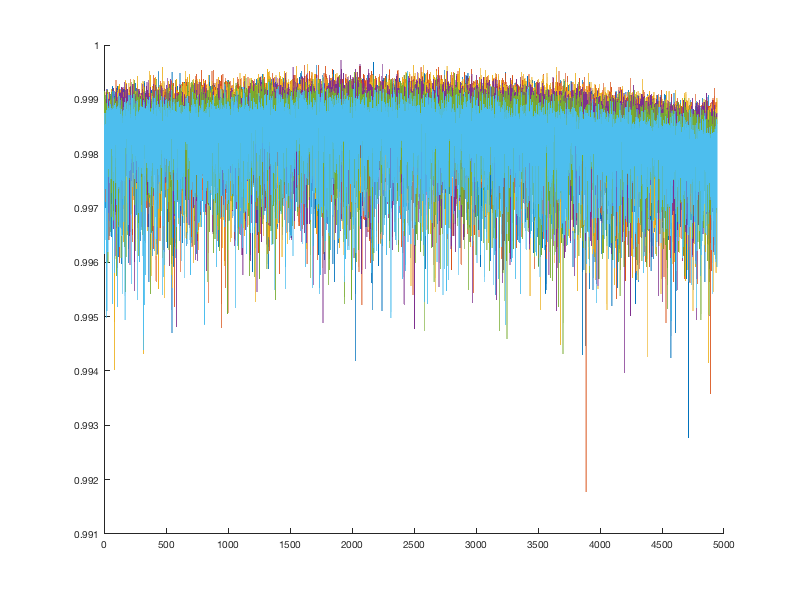

figure('Position',[1 1 800 600])
hold on
for row = 500:500:3000
    plot(normflat(row,:,chnl))
end
hold off